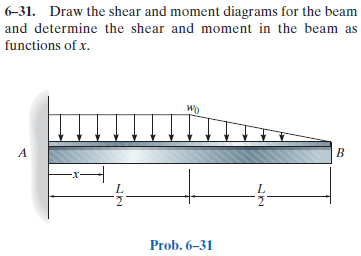

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-31P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-31P-solution-9780136022305)  

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
wo = sym('wo');
L = sym('L', 'positive');
w1(x) = -wo;
w2 = findpoly(1, 'thru', [L/2 -wo], [L 0]);

# beam

b = beam; 
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('distributed', 'force', w1, [0 L/2]);
b = b.add('distributed', 'force', w2, [L/2 L], [false true]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x^{2}\,\left(7\,L^{2}-6\,L\,x+2\,x^{2}\right)}{48\,\text{E}\,\text{I}} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L^{5}-10\,L^{4}\,x+320\,L^{3}\,x^{2}-320\,L^{2}\,x^{3}+160\,L\,x^{4}-32\,x^{5}\right)}{1920\,\text{E}\,\text{I}\,L} & \text{ if }L<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(7\,L^{2}-9\,L\,x+4\,x^{2}\right)}{24\,\text{E}\,\text{I}} & \text{ if }2\,x\leq L\\ \frac{\mathrm{wo}\,\left(L^{4}-64\,L^{3}\,x+96\,L^{2}\,x^{2}-64\,L\,x^{3}+16\,x^{4}\right)}{192\,\text{E}\,\text{I}\,L} & \text{ if }L<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(7\,L^{2}-18\,L\,x+12\,x^{2}\right)}{24} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,{\left(L-x\right)}^{3}}{3\,L} & \text{ if }L<2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(3\,L-4\,x\right)}{4} & \text{ if }2\,x\leq L\\ \frac{\mathrm{wo}\,{\left(L-x\right)}^{2}}{L} & \text{ if }L<2\,x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\mathrm{wo} & \text{ if }2\,x\leq L\\ -\frac{2\,\mathrm{wo}\,\left(L-x\right)}{L} & \text{ if }L<2\,x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{7\,L^{2}\,\mathrm{wo}}{24}\\ \mathrm{Ra} & \frac{3\,L\,\mathrm{wo}}{4} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

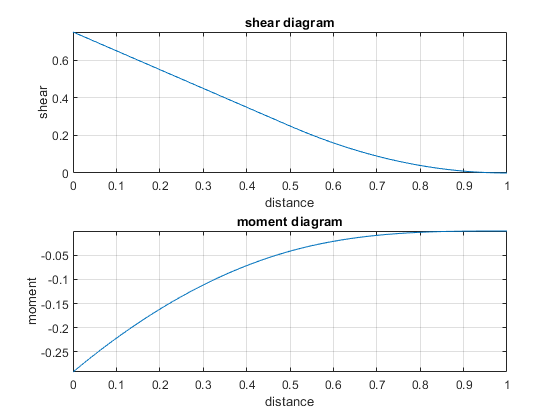

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;